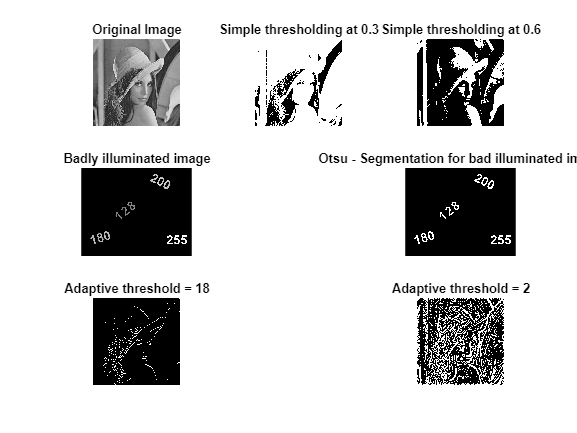

clc;
close all;
clear all;

a = imread("lena_gray.jpeg");

subplot(3,3,1);
imshow(a); title('Original Image');

level = 0.3;
subplot(3,3,2);
segimage1 = im2bw(a, level);
imshow(segimage1); title('Simple thresholding at 0.3');

subplot(3,3,3);
imshow(a > 153); title('Simple thresholding at 0.6');

b = imread("Otsu.png");
subplot(3,3,4);
imshow(b); title('Badly illuminated image');

level = graythresh(b);
subplot(3,3,6);
segimage = im2bw(b, level);
imshow(segimage); title('Otsu - Segmentation for bad illuminated image');

b = imread("lena_gray.jpeg");


avgfilt = ones(13,13);
adaptfiltmask = avgfilt/sum(avgfilt);
im = imfilter(b, adaptfiltmask, 'replicate');

im1 = medfilt2(b, [20 20]);
thresh = im + 18;
adaptthresimg = b - thresh;
subplot(3,3,7);
imshow(adaptthresimg > 0); title('Adaptive threshold = 18');

thresh1 = im1 + 2;
adaptthresimg = b - thresh1;
subplot(3,3,9);
imshow(adaptthresimg > 0); title('Adaptive threshold = 2')